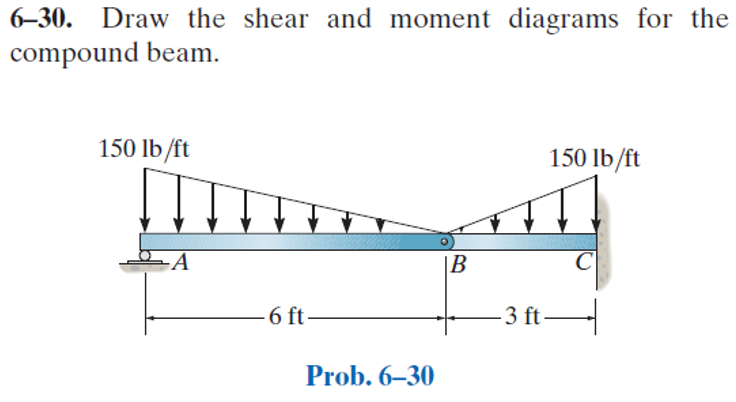

[https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-30P-solution-9780136022305](https://www.chegg.com/homework-help/Mechanics-of-Materials-8th-edition-chapter-6-problem-30P-solution-9780136022305) 

# assumptions

u = symunit;
old_assum = assumptions;
clearassum;

# distributed load formulas

w1 = findpoly(1, 'thru', [0 -150*u.lbf/u.ft], [6*u.ft 0]);
w2 = findpoly(1, 'thru', [6*u.ft 0], [9*u.ft -150*u.lbf/u.ft]);

# beam

b = beam;
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rc', 9*u.ft);
b = b.add('reaction', 'moment', 'Mc', 9*u.ft);
b = b.add('hinge', 'force', 'Hb', 6*u.ft);
b = b.add('distributed', 'force', w1, [0 6]*u.ft);
b = b.add('distributed', 'force', w2, [6 9]*u.ft, [false true]);
b.L = 9*u.ft;

# solution

[y dy m v w rs ra hs ha] = b.elastic_curve('Mode', 'factor');

# elastic curve

y

$$y(x) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(-x^{4}+30\,x^{3}\,\mathrm{ft}-240\,x^{2}\,{\mathrm{ft}}^{2}+4860\,{\mathrm{ft}}^{4}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{5\,{\left(x-9\,\mathrm{ft}\right)}^{2}\,\left(x^{3}-12\,x^{2}\,\mathrm{ft}+123\,x\,{\mathrm{ft}}^{2}-54\,{\mathrm{ft}}^{3}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

dy

$$dy(x) = \left\{ \begin{array}{cl} -\frac{25\,\left(x^{2}-18\,x\,\mathrm{ft}+54\,{\mathrm{ft}}^{2}\right)\,\left(-x^{2}+6\,x\,\mathrm{ft}+18\,{\mathrm{ft}}^{2}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{25\,\left(x-3\,\mathrm{ft}\right)\,\left(x-9\,\mathrm{ft}\right)\,\left(x^{2}-12\,x\,\mathrm{ft}+81\,{\mathrm{ft}}^{2}\right)}{12\,\text{E}\,\text{I}}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{25\,x\,\left(x-6\,\mathrm{ft}\right)\,\left(x-12\,\mathrm{ft}\right)}{6}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -\frac{25\,\left(x-6\,\mathrm{ft}\right)\,\left(x^{2}-12\,x\,\mathrm{ft}+54\,{\mathrm{ft}}^{2}\right)}{3}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{25\,\left(x^{2}-12\,x\,\mathrm{ft}+24\,{\mathrm{ft}}^{2}\right)}{2}\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -25\,\left(x^{2}-12\,x\,\mathrm{ft}+42\,{\mathrm{ft}}^{2}\right)\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 25\,\left(x-6\,\mathrm{ft}\right)\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }x\leq 6\,\mathrm{ft}\\ -50\,\left(x-6\,\mathrm{ft}\right)\,\frac{\mathrm{lbf}}{{\mathrm{ft}}^{2}} & \text{ if }6\,\mathrm{ft}<x \end{array}\right.$$

# reactions and hinges

ra

$$ra = \left(\begin{array}{cc} \mathrm{Mc} & -675\,\mathrm{ft}\,\mathrm{lbf}\\ \mathrm{Ra} & 300\,\mathrm{lbf}\\ \mathrm{Rc} & 375\,\mathrm{lbf} \end{array}\right)$$

ha

$$ha = \left(\begin{array}{cc} \mathrm{Hb} & 150\,\mathrm{lbf} \end{array}\right)$$

# shear and moment diagram

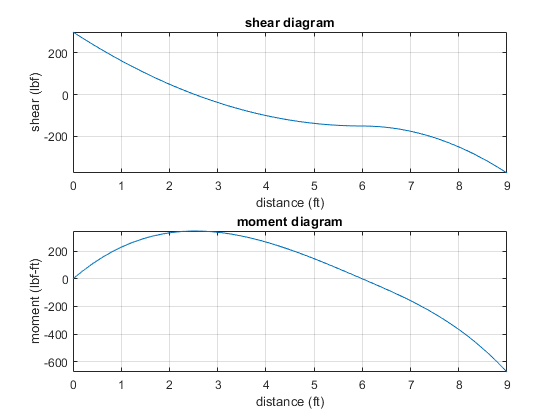

beam.shear_moment(m, v, [0 b.L], {'lbf' 'ft'});

# clean up

addvar(y);
assume(old_assum);
clear old_assum;